GEOMETRIC CONTROL

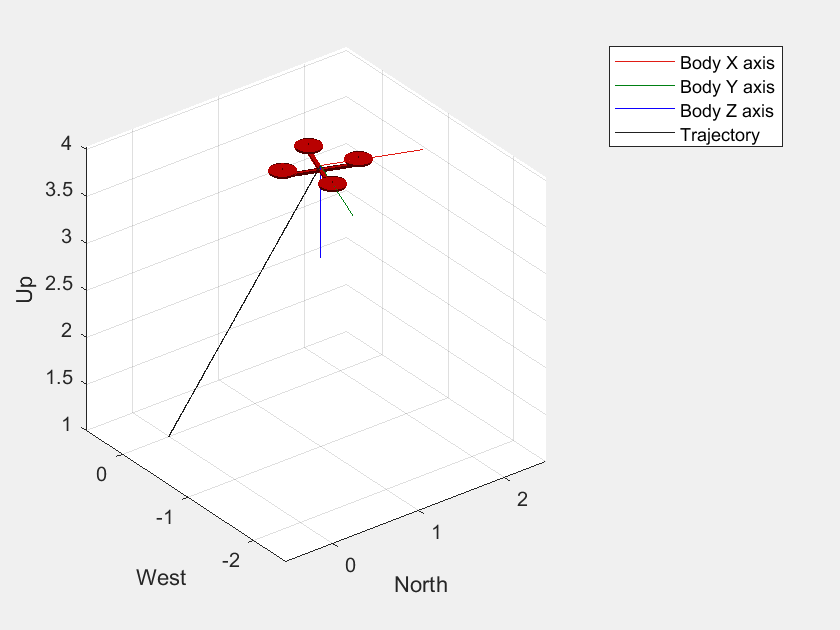

sim('geometric_control_template.slx');

pos = ans.pos.data;
pos_des = ans.pos_des.data;
len = length(ans.pos_des.data);
t = 0 : (len-1);
lin_vel_des = ans.lin_vel_des.data;
lin_acc_des = ans.lin_acc_des.data;
lin_vel = ans.lin_vel.data;
xb_des = ans.xb_des.data;
err_p = ans.err_p.data;
dot_err_p = ans.dot_err_p.data;
dot_omega_bb = ans.dot_omega_bb.data;
err_R = ans.err_R.data;
err_W = ans.err_W.data;
uT = ans.uT.data;
tau_b = ans.tau_b.data;
omega_bb = ans.omega_bb.data;
Rb = ans.Rb.data;
euler_angles = ans.euler_angles.data;
yaw = squeeze(euler_angles(1,1,:));
euler_angles_des = ans.euler_angles_des.data;
yaw_des = squeeze(euler_angles_des(1,1,:));

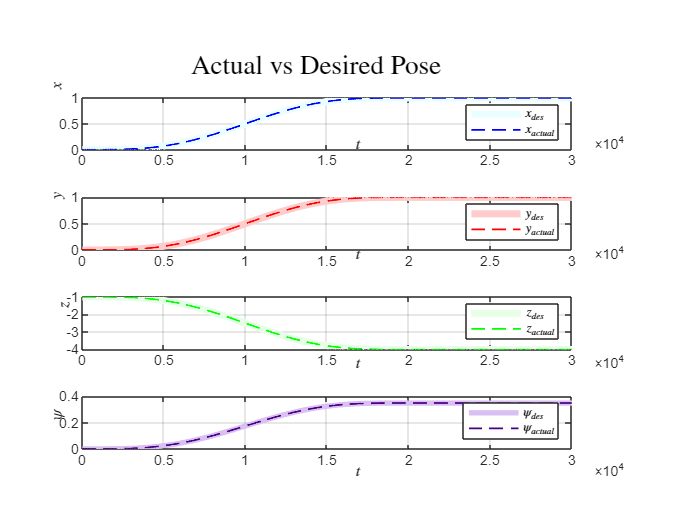

figure
subplot(4,1,1)
plot(t, pos_des(:,1), 'LineWidth', 4,'Color', [235/255, 254/255, 255/255], 'DisplayName', '$x_{des}$');
hold on
plot(t, pos(:,1), 'LineWidth', 1, 'Color', 'b', 'LineStyle', '--', 'DisplayName', '$x_{actual}$');
xlabel('$t$','Interpreter','latex')
ylabel('$x$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(4,1,2)
plot(t, pos_des(:,2), 'LineWidth', 4,'Color', [1, 0.8, 0.8], 'DisplayName', '$y_{des}$');
hold on
plot(t, pos(:,2), 'LineWidth', 1,'Color', 'r', 'LineStyle', '--', 'DisplayName', '$y_{actual}$');
xlabel('$t$','Interpreter','latex')
ylabel('$y$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(4,1,3)
plot(t, pos_des(:,3), 'LineWidth', 4,'Color', [0.9, 1, 0.9], 'DisplayName', '$z_{des}$');
hold on
plot(t, pos(:,3), 'LineWidth', 1, 'Color', 'g', 'LineStyle', '--', 'DisplayName', '$z_{actual}$');
xlabel('$t$','Interpreter','latex')
ylabel('$z$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(4,1,4)
plot(t, yaw_des, 'LineWidth', 3,'Color', [0.85, 0.75, 0.95], 'DisplayName', '$\psi_{des}$');
hold on
plot(t, yaw, 'LineWidth', 1, 'Color', 	[0.29, 0, 0.51],'LineStyle', '--', 'DisplayName', '$\psi_{actual}$');
xlabel('$t$','Interpreter','latex')
ylabel('$\psi$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('Actual vs Desired Pose','Interpreter','latex')
print(gcf, 'ex4_pos_vs_despos_and_yaw', '-dpdf', '-r150'); 

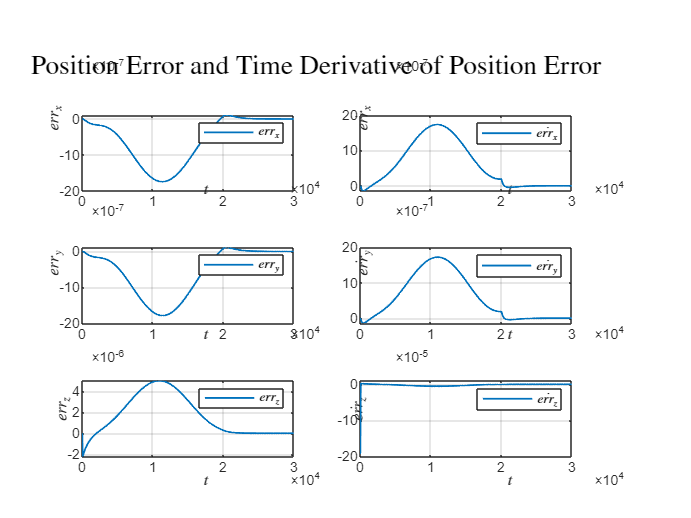


figure
subplot(3,2,1)
plot(t, err_p(:,1), 'LineWidth', 1, 'DisplayName', '$err_x$');
xlabel('$t$','Interpreter','latex')
ylabel('$err_x$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,3)
plot(t, err_p(:,2), 'LineWidth', 1, 'DisplayName', '$err_y$');
xlabel('$t$','Interpreter','latex')
ylabel('$err_y$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,5)
plot(t, err_p(:,3), 'LineWidth', 1, 'DisplayName', '$err_z$');
xlabel('$t$','Interpreter','latex')
ylabel('$err_z$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,2)
plot(t, dot_err_p(:,1), 'LineWidth', 1, 'DisplayName', '$\dot{err_x}$');
xlabel('$t$','Interpreter','latex')
ylabel('$\dot{err_x}$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,4)
plot(t, dot_err_p(:,2), 'LineWidth', 1, 'DisplayName', '$\dot{err_y}$');
xlabel('$t$','Interpreter','latex')
ylabel('$\dot{err_y}$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,6)
plot(t, dot_err_p(:,3), 'LineWidth', 1, 'DisplayName', '$\dot{err_z}$');
xlabel('$t$','Interpreter','latex')
ylabel('$\dot{err_z}$','Interpreter','latex')
ylim([-20e-5,1e-5])
grid on
legend('Interpreter', 'latex');
sgtitle('Position Error and Time Derivative of Position Error','Interpreter','latex')
print(gcf, 'ex4_pos_&_vel_err', '-dpdf', '-r150'); 

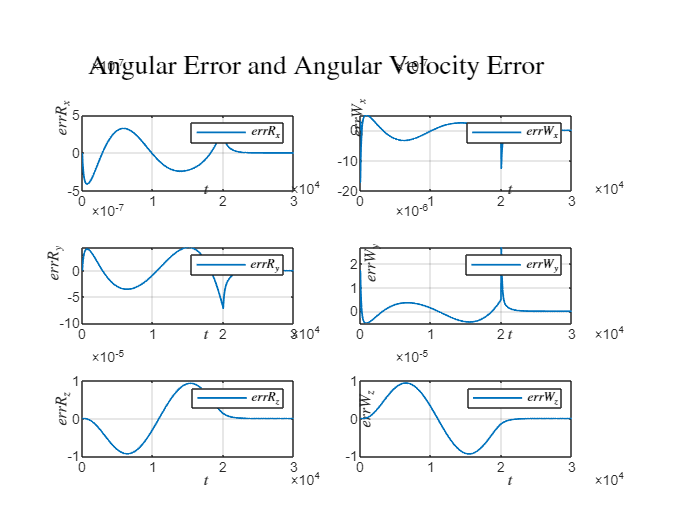


figure
subplot(3,2,1)
plot(t, err_R(:,1), 'LineWidth', 1, 'DisplayName', '$errR_x$');
xlabel('$t$','Interpreter','latex')
ylabel('$errR_x$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,3)
plot(t, err_R(:,2), 'LineWidth', 1, 'DisplayName', '$errR_y$');
xlabel('$t$','Interpreter','latex')
ylabel('$errR_y$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,5)
plot(t, err_R(:,3), 'LineWidth', 1, 'DisplayName', '$errR_z$');
xlabel('$t$','Interpreter','latex')
ylabel('$errR_z$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,2)
plot(t, err_W(:,1), 'LineWidth', 1, 'DisplayName', '$errW_x$');
xlabel('$t$','Interpreter','latex')
ylabel('$errW_x$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,4)
plot(t, err_W(:,2), 'LineWidth', 1, 'DisplayName', '$errW_y$');
xlabel('$t$','Interpreter','latex')
ylabel('$errW_y$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,2,6)
plot(t, err_W(:,3), 'LineWidth', 1, 'DisplayName', '$errW_z$');
xlabel('$t$','Interpreter','latex')
ylabel('$errW_z$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('Angular Error and Angular Velocity Error','Interpreter','latex')
print(gcf, 'ex4_ang_&_ang_vel_err', '-dpdf', '-r300');

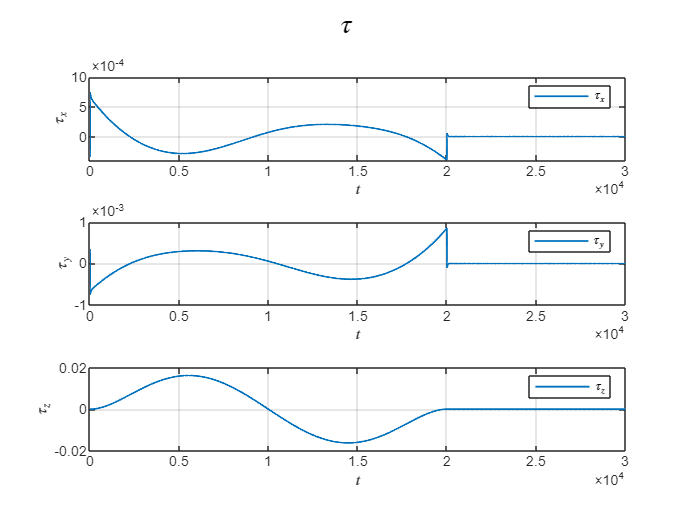

figure
subplot(3,1,1)
plot(t, tau_b(:,1), 'LineWidth', 1, 'DisplayName', '$\tau_x$');
xlabel('$t$','Interpreter','latex')
ylabel('$\tau_x$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,1,2)
plot(t, tau_b(:,2), 'LineWidth', 1, 'DisplayName', '$\tau_y$');
xlabel('$t$','Interpreter','latex')
ylabel('$\tau_y$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
subplot(3,1,3)
plot(t, tau_b(:,3), 'LineWidth', 1, 'DisplayName', '$\tau_z$');
xlabel('$t$','Interpreter','latex')
ylabel('$\tau_z$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('$\tau$','Interpreter','latex')
print(gcf, 'ex4_tau', '-dpdf', '-r150'); 

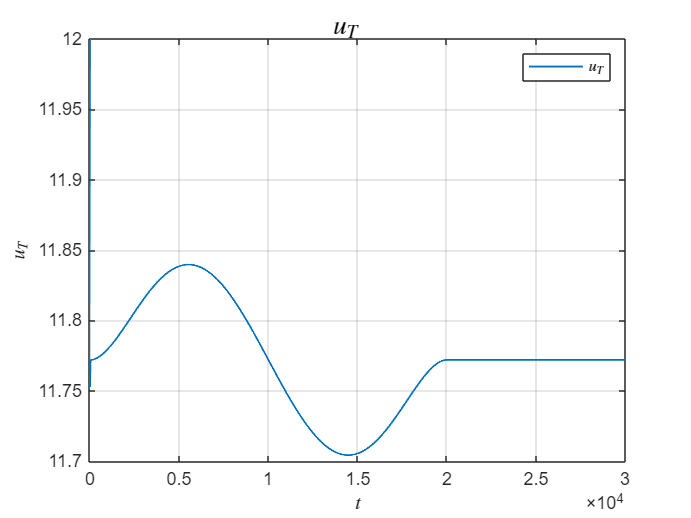

figure
plot(t, uT, 'LineWidth', 1, 'DisplayName', '$u_T$');
xlabel('$t$','Interpreter','latex')
ylabel('$u_T$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('$u_T$','Interpreter','latex')
print(gcf, 'ex4_uT', '-dpdf', '-r150'); 

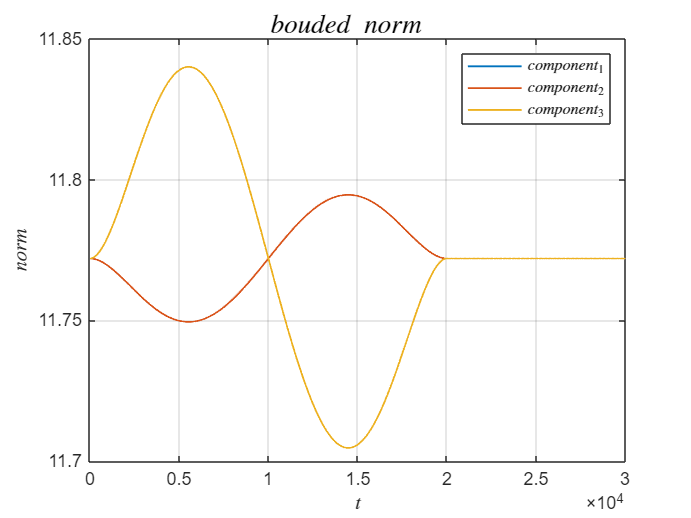

quant = zeros(length(t),3);
for i = 1 : 3
    for j = 1 : length(t)
        quant(j,i) = norm(- mass*9.81*[0,0,1]' + mass*lin_acc_des(j,i));
    end
end

figure
plot(t, quant(:,1), 'LineWidth', 1, 'DisplayName', '$component_1$'); hold on;
plot(t, quant(:,2), 'LineWidth', 1, 'DisplayName', '$component_2$');
plot(t, quant(:,3), 'LineWidth', 1, 'DisplayName', '$component_3$');
xlabel('$t$','Interpreter','latex')
ylabel('$norm$','Interpreter','latex')
grid on
legend('Interpreter', 'latex');
sgtitle('$bouded \ norm$','Interpreter','latex')
print(gcf, 'ex4_constant', '-dpdf', '-r150'); 